## Final Exam Review

## Exam 1

Question 1 is a problem review the initial and final value theorems:

- Initial Value Theorem: f (0+ ) = lim+ f (t) = as s -> infinity lim sF (s)

- Final Value Theorem: f (∞) = lim f (t) = lim sF (s) (s approaches 0)

clear;
syms s

$$Gs = -\frac{2\,s+14}{s^{2}-2\,s+10}$$

Gs = (-2*(s+7)) / (s^2 -2*s+10)

$$limGs = -\frac{s\,\left(2\,s+14\right)}{s^{2}-2\,s+10}$$

limGs = s*Gs

ans =    1.0000 + 3.0000i
   1.0000 - 3.0000i


roots([1,-2,10])

Question 2 is about Determining step response type:

- Overdamped ($$\zeta$$>1)

- Underdamped ($$\zeta$$<1)

- Critcally Damped ($$\zeta$$=1)

- Undamped ($$\zeta$$=0)

clear;


s =
 
  s
 
Continuous-time transfer function.
Model Properties


s = tf('s')


Gs =
 
     10 s + 30
  ----------------
  s^2 + 30 s + 200
 
Continuous-time transfer function.
Model Properties


Gs = 10*(s+3)/(s^2+30*s+200)

poles =    -20
   -10


OS = -1.0000e+02 - 6.7380e-13i

Tp = 0.0000 - 0.6283i

Ts = 0.2667

Tr = 0.2640

ans = struct with fields:
      wn: 14.1421
    zeta: 1.0607


secondOrderFromTF(Gs) %overdamped

clear;


s =
 
  s
 
Continuous-time transfer function.
Model Properties


s = tf('s')


Gs =
 
       s + 2
  ----------------
  s^2 + 20 s + 100
 
Continuous-time transfer function.
Model Properties


Gs = (s+2)/(s^2+20*s+100)

poles =    -10
   -10


OS = 0

Tp = Inf

Ts = 0.4000

Tr = 0.3382

ans = struct with fields:
      wn: 10
    zeta: 1


secondOrderFromTF(Gs) %crit damped

clear



s =
 
  s
 
Continuous-time transfer function.
Model Properties


s = tf('s')


Gs =
 
        17
  --------------
  s^2 + 4 s + 13
 
Continuous-time transfer function.
Model Properties


Gs = 17/(s^2+4*s+13)

poles =   -2.0000 + 3.0000i
  -2.0000 - 3.0000i


OS = 12.3145

Tp = 1.0472

Ts = 2

Tr = 0.4849

ans = struct with fields:
      wn: 3.6056
    zeta: 0.5547


secondOrderFromTF(Gs) %underdamped

clear;


s =
 
  s
 
Continuous-time transfer function.
Model Properties


s = tf('s')


Gs =
 
   s + 5
  --------
  s^2 + 16
 
Continuous-time transfer function.
Model Properties


Gs = (s+5)/(s^2+16)

poles =    0.0000 + 4.0000i
   0.0000 - 4.0000i


OS = 100

Tp = 0.7854

Ts = Inf

Tr = 0.2500

ans = struct with fields:
      wn: 4
    zeta: 0


secondOrderFromTF(Gs) %undamped

Question 2b is about step response parameters.

- These are found in the function used above

Question 3 - use laplace methods to solve for the complete solution for the following differential equation:


$$\[
\mathcal{L}\{x(t)\} = X(s)
\]

\[
\mathcal{L}\{\dot{x}(t)\} = sX(s) - x(0)
\]

\[
\mathcal{L}\{\ddot{x}(t)\} = s^2X(s) - s x(0) - \dot{x}(0)
\]

\[
\mathcal{L}\{t\} = \frac{1}{s^2}
\]
$$


clear;
syms s
Xs1 = (s^3-2*s^2+1)/(s^2*(s^2+1));

$$Xs = \frac{s^{3}-2\,s^{2}+1}{s^{2}\,\left(s^{2}+1\right)}$$

Xs = simplify(Xs1)


$$xt = t+\cos\left(t\right)-3\,\sin\left(t\right)$$

xt = ilaplace(Xs)

Question 4 - Initial Conditions of a circuit

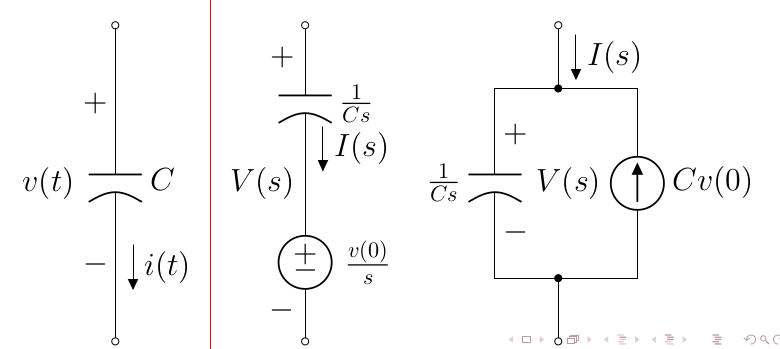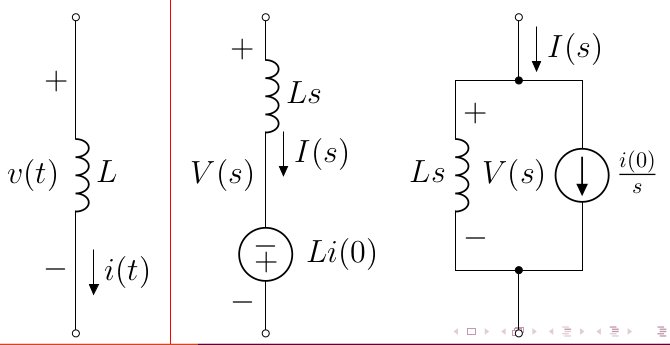

clear;
syms i1 i2 s

% Parameters
L = 0.8;         % H
C = 5e-6;        % F
R = 250;         % Ohms

% Initial conditions
iL0 = 9/250;     % Initial current through inductor
vC0 = 9;         % Initial voltage across capacitor

% Laplace impedances
ZL = L*s;
ZC = 1/(C*s);

% Voltage sources from initial conditions
VL0 = L*iL0;     % Initial inductor voltage source
IC0 = C*vC0;     % Initial capacitor current source (not directly used here)

% Modified KVL equations using superposition of impedance and initial sources
eqn1 = i1*ZL - VL0 + (i1 - i2)*ZC + vC0/s == 0;
eqn2 = i2*R + (i2 - i1)*ZC - vC0/s == 0;

[i1soln, i2soln] = solve(eqn1, eqn2, [i1, i2]);

$$i1simp = 0.036\,{\mathrm{e}}^{-400.0\,t}\,\left(\cos\left(300.0\,t\right)+0.291667\,\sin\left(300.0\,t\right)\right)$$

i1simp = vpa(ilaplace(i1soln),6)

$$i2simp = 0.036\,{\mathrm{e}}^{-400.0\,t}\,\left(\cos\left(300.0\,t\right)+1.33333\,\sin\left(300.0\,t\right)\right)$$

i2simp = vpa(ilaplace(i2soln),6)

$$Vct = 9.0\,{\mathrm{e}}^{-400.0\,t}\,\left(\cos\left(300.0\,t\right)+1.33333\,\sin\left(300.0\,t\right)\right)$$

Vct = vpa(i2simp * 250,6)


Question 4

Transfer function

clear;
syms Vo VA Vi s Z0 Z1
digits(6);
Z0subs = 500e3 + 1/(2e-6*s);
Z1subs = 200e3 + 1/(2e-6*s);
eqn = (-Vi)/Z0 + (-Vo) / Z1 ==0;

$$vout = -\frac{Z_{1}}{Z_{0}}$$

vout = solve(eqn,Vo) / Vi

$$Gs = -\frac{\frac{2361183241434822606848}{4722366482869645\,s}+200000}{\frac{2361183241434822606848}{4722366482869645\,s}+500000}$$

Gs = subs(vout,{Z0,Z1},{Z0subs,Z1subs})
Gs = simplify(vpa(Gs));

$$step = \frac{1}{s}$$

step = 1/s

$$Cs = -\frac{1.0\,\left(2.0\,s+5.0\right)}{s\,\left(5\,s+5.0\right)}$$

Cs = Gs*step

$$ct = 0.6\,{\mathrm{e}}^{-1.0\,t}-1.0$$

ct = ilaplace(Cs)


## EXAM II

Question 1 - System Type, Error, and System Parameters


$$$Ts = \frac{4}{Real part} = \frac{4}{\zeta\omega_n}$
$$



$$\zeta = \frac{a/2}{\omega_n}$$
 


$$\omega_n = \sqrt{b}$$


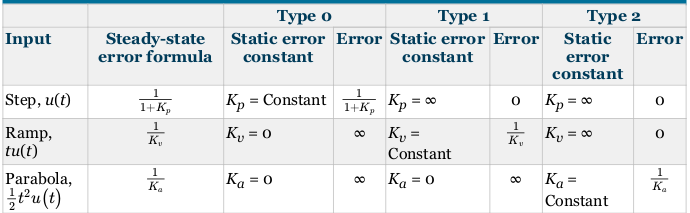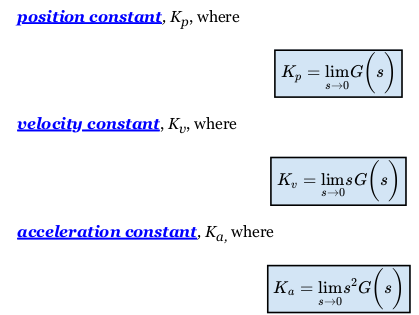


$$E(s) = \frac{R(s)}{ 1+G(s)}$$


clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 1/(s*(s+6))


Gs =
 
      1
  ---------
  s^2 + 6 s
 
Continuous-time transfer function.
Model Properties



clear;
syms s K
Gs = K/(s*(s+6))

$$Gs = \frac{K}{s\,\left(s+6\right)}$$

Ts = Gs/(1+Gs);
simplify(Ts)

$$ans = \frac{K}{s^{2}+6\,s+K}$$

%{
kp = subs(Gs,s,0) %infinity
1/1+kp % 1/ inf
%}
%find %os based on K
wn = sqrt(K)

$$wn = \sqrt{K}$$

zeta = (6/2)/(wn)

$$zeta = \frac{3}{\sqrt{K}}$$

e = exp(1)

e = 2.7183

eqn = 10 == e^((-zeta*pi)/(sqrt(1-zeta^2))) * 100

$$eqn = 10=\frac{100}{{\left(\frac{6121026514868073}{2251799813685248}\right)}^{\frac{3\,\pi }{\sqrt{K}\,\sqrt{1-\frac{9}{K}}}}}$$

vpa(solve(eqn,K))

$$ans = 25.753705514304815400145169137928$$

4/(wn*zeta)                                                                                 

$$ans = \frac{4}{3}$$

Question 2

- TS of a wierder block diagram

Gs = (s^3+1)/s^2;
Hs = 1;
Ts = simplify(Gs /(1+Gs*Hs))

$$Ts = \frac{s^{3}+1}{s^{3}+s^{2}+1}$$

Question 3

- a) Pole location using Routh Hurwitz

- b) Range and stability of a new system using routh hurwitz

clear;
syms s
Gs = 1/(s^4+s^3+64)

$$Gs = \frac{1}{s^{4}+s^{3}+64}$$

Hs = 1/s

$$Hs = \frac{1}{s}$$


Ts = simplify(Gs/(1+Gs*Hs))

$$Ts = \frac{s}{s^{5}+s^{4}+64\,s+1}$$

den = {1,1,0,0,64,1}

den = 1×6 cell array
    {[1]}    {[1]}    {[0]}    {[0]}    {[64]}    {[1]}


RouthHurwitz(den)


Zero in first collumn occurred

 Final Routh Table 


$$\left(\begin{array}{ccc} 1 & 0 & 64\\ 1 & 0 & 1\\ \mathrm{epss} & 63 & 0\\ -\frac{63}{\mathrm{epss}} & 1 & 0\\ \frac{{\mathrm{epss}}^{2}}{63}+63 & 0 & 0\\ 1 & 0 & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{ccc} 1 & 0 & 64\\ 1 & 0 & 1\\ \mathrm{epss} & 63 & 0\\ -\frac{63}{\mathrm{epss}} & 1 & 0\\ \frac{{\mathrm{epss}}^{2}}{63}+63 & 0 & 0\\ 1 & 0 & 0 \end{array}\right)$$

b

clear;
syms s K
Gs = (K*(s+3)*(s+5))/((s-2)*(s+4))

$$Gs = \frac{K\,\left(s+3\right)\,\left(s+5\right)}{\left(s-2\right)\,\left(s+4\right)}$$

Ts = simplify(Gs/(1+Gs))

$$Ts = \frac{K\,\left(s+3\right)\,\left(s+5\right)}{\left(\frac{K\,\left(s+3\right)\,\left(s+5\right)}{\left(s-2\right)\,\left(s+4\right)}+1\right)\,\left(s-2\right)\,\left(s+4\right)}$$

simplify(Ts)

$$ans = \frac{K\,\left(s+3\right)\,\left(s+5\right)}{\left(\frac{K\,\left(s+3\right)\,\left(s+5\right)}{\left(s-2\right)\,\left(s+4\right)}+1\right)\,\left(s-2\right)\,\left(s+4\right)}$$

collect(Ts,s)

$$ans = \frac{K\,s^{2}+\left(8\,K\right)\,s+15\,K}{\left(K+1\right)\,s^{2}+\left(8\,K+2\right)\,s+15\,K-8}$$


den = {(K+1),8*K+2,15*K-8}

den = 1×3 cell array
    {[K + 1]}    {[8*K + 2]}    {[15*K - 8]}


simplify(RouthHurwitz(den))


 Final Routh Table 


$$\left(\begin{array}{cc} K+1 & 15\,K-8\\ 8\,K+2 & 0\\ \frac{2\,\left(4\,K+1\right)\,\left(15\,K-8\right)}{8\,K+2} & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{cc} K+1 & 15\,K-8\\ 8\,K+2 & 0\\ 15\,K-8 & 0 \end{array}\right)$$

Question 4

clear;
syms s K
Gs = (K*(s^2+6*s+6))/((s+5)^2*(s+3))

$$Gs = \frac{K\,\left(s^{2}+6\,s+6\right)}{\left(s+3\right)\,{\left(s+5\right)}^{2}}$$

Rs = 12/s^2

$$Rs = \frac{12}{s^{2}}$$



Kp = subs(Gs,s,0)

$$Kp = \frac{2\,K}{25}$$

disp(vpa(Kp));

$$0.08\,K$$

estep = 1/(1+Kp)

$$estep = \frac{1}{\frac{2\,K}{25}+1}$$

disp(vpa(estep));

$$\frac{1}{0.08\,K+1.0}$$


Kramp = subs(s*Gs,s,0)

$$Kramp = 0$$

%eramp = 1/Kramp is infinity

Question 5

More transfer function ans system type

clear;
syms s

Gs = (100*(s+2))/(s*(s+5))

$$Gs = \frac{100\,s+200}{s\,\left(s+5\right)}$$

Hs = 6

Hs = 6


Ts = Gs/(1+Gs*Hs)

$$Ts = \frac{100\,s+200}{s\,\left(s+5\right)\,\left(\frac{6\,\left(100\,s+200\right)}{s\,\left(s+5\right)}+1\right)}$$

Ts = simplify(Ts)

$$Ts = \frac{100\,s+200}{s^{2}+605\,s+1200}$$


Ts = simplify(Ts*(1000/s))

$$Ts = \frac{1000\,\left(100\,s+200\right)}{s\,\left(s^{2}+605\,s+1200\right)}$$

poles(Ts)

$$ans = \left(\begin{array}{c} \frac{5\,\sqrt{14449}}{2}-\frac{605}{2}\\ -\frac{5\,\sqrt{14449}}{2}-\frac{605}{2}\\ 0 \end{array}\right)$$


Gs = Ts / (1-Ts)

$$Gs = -\frac{1000\,\left(100\,s+200\right)}{s\,\left(\frac{1000\,\left(100\,s+200\right)}{s\,\left(s^{2}+605\,s+1200\right)}-1\right)\,\left(s^{2}+605\,s+1200\right)}$$

simplify(Gs)

$$ans = -\frac{100000\,s+200000}{-s^{3}-605\,s^{2}+98800\,s+200000}$$


Kp = subs(Gs,s,0)

Error using sym/subs (line 156)
Division by zero.

Question 6

- Computing the asymtotes and angles 

- computing the break in/away points

clear;
syms s 
Gs = 1/((s+1)*(s+2)*(s+3)*(s+4))

$$Gs = \frac{1}{\left(s+1\right)\,\left(s+2\right)\,\left(s+3\right)\,\left(s+4\right)}$$

Hs = 1

Hs = 1

K = -1/(Gs*Hs);
dK =diff(K,s)

$$dK = -\left(s+1\right)\,\left(s+2\right)\,\left(s+3\right)-\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)-\left(s+1\right)\,\left(s+3\right)\,\left(s+4\right)-\left(s+2\right)\,\left(s+3\right)\,\left(s+4\right)$$

dK =collect(dK,s)

$$dK = -4\,s^{3}-30\,s^{2}-70\,s-50$$

roots_of_p = solve(dK == 0, s)

$$roots\_of\_p = \left(\begin{array}{c} -\frac{5}{2}\\ -\frac{\sqrt{5}}{2}-\frac{5}{2}\\ \frac{\sqrt{5}}{2}-\frac{5}{2} \end{array}\right)$$

vpa(roots_of_p)

$$ans = \left(\begin{array}{c} -2.5\\ -3.6180339887498948482045868343656\\ -1.3819660112501051517954131656344 \end{array}\right)$$

clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 1/((s+1)*(s+2)*(s+3)*(s+4))


Gs =
 
                  1
  ---------------------------------
  s^4 + 10 s^3 + 35 s^2 + 50 s + 24
 
Continuous-time transfer function.
Model Properties


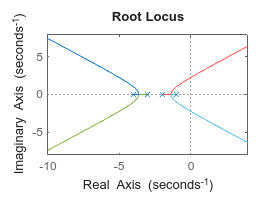

rlocus(Gs)

%routh method
clear;
syms s K
Gs = K/((s+1)*(s+2)*(s+3)*(s+4))

$$Gs = \frac{K}{\left(s+1\right)\,\left(s+2\right)\,\left(s+3\right)\,\left(s+4\right)}$$

Ts = Gs/(1+Gs)

$$Ts = \frac{K}{\left(\frac{K}{\left(s+1\right)\,\left(s+2\right)\,\left(s+3\right)\,\left(s+4\right)}+1\right)\,\left(s+1\right)\,\left(s+2\right)\,\left(s+3\right)\,\left(s+4\right)}$$

Ts = simplify(Ts)

$$Ts = \frac{K}{s^{4}+10\,s^{3}+35\,s^{2}+50\,s+K+24}$$

den = {1,10,35,50,K+24}

den = 1×5 cell array
    {[1]}    {[10]}    {[35]}    {[50]}    {[K + 24]}


simplify(RouthHurwitz(den))


 Final Routh Table 


$$\left(\begin{array}{ccc} 1 & 35 & K+24\\ 10 & 50 & 0\\ 30 & K+24 & 0\\ 42-\frac{K}{3} & 0 & 0\\ \frac{\left(K+24\right)\,\left(K-126\right)}{3\,\left(\frac{K}{3}-42\right)} & 0 & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{ccc} 1 & 35 & K+24\\ 10 & 50 & 0\\ 30 & K+24 & 0\\ 42-\frac{K}{3} & 0 & 0\\ K+24 & 0 & 0 \end{array}\right)$$

## Homework 9 and 10